# Fase Esplorativa MTV-KI bozza

## Crea cartella datata

 
oggi = string(datetime('now','Format','dd-MM-yy'));
percorso = strcat('Fase1_',oggi);
if ~exist(percorso, 'dir')
    mkdir(percorso);
    addpath(percorso);
    disp("Creata cartella datata per oggi: "+oggi);
end

Creata cartella datata per oggi: 27-01-23


## Inizializzazione Tactors

 
addpath("MATLAB64_TDK-1.0.5.0\")
ti = TactorInterfaceML;

Loading dll...
Dll loaded!
Initialized Tactor Interface.



numFound = ti.Discover;

Discovering... (this will take a while.)
Discover returned:3


 
if (numFound > 0)
    for devIndex = 0:(numFound-1)
        [dev, type] = ti.GetDevice(devIndex)
        if dev == "\\.\COM13"
            ti.Connect(dev, type);
        end
    end
end

GetDevice:COM6


dev = 'COM6'

type = 1

GetDevice:COM7


dev = 'COM7'

type = 1

GetDevice:\\.\COM13


dev = '\\.\COM13'

type = 1

Connect returned:0


## Inizializza CyberGlove

 
port = portaseriale("glove");

Available serial COMs are: 
COM1
COM6
COM7
COM14
 
    "Which one do yo want to open forglove?"



glove = Cyberglove(port);

Streaming Frame Rate set to 30Hz


delete(glove)

Unrecognized function or variable 'glove'.

clear glove

## Calibrazione CyberGlove

Pinga il guanto per la ricezione di una singola stringa di dati di posizione.

Si può pingare più volte e i dati vengono appesi nella variabile tab.

In questo momento questo script esegue delle misurazioni di posizione, dai quali calcolare max e min della rom del movimento che ci interessa (dita estese-dita flesse alla metacarpo-falangea).

TODO:

1) Capire come da questi dati estrarre gli scaling factors da applicare ai dati streammati in seguito

2) Questo scaling lo facciamo a posteriori una volta raccolti i dati raw? (secondo me sì)

 

if exist("DataTags.mat","file") ~= 0
    load DataTags.mat
end


num = glove.serial_p.NumBytesAvailable

num = 1


write(glove.serial_p, 'G', 'uint8');

data = read(glove.serial_p, 20, 'uint8')

data =     71     3    15    80   110    68    57    78    32   170    92    76   143   104    62   164   149   146    56     0


write(glove.serial_p, 'C', 'uint8');

called = read(glove.serial_p, 7, 'uint8')

called =     67    32   101    63    13    10     0


write(glove.serial_p, '?c', 'uint8');
% cal_verb = read(glove.serial_p, 52, 'uint8')

nocal = importClosure("Closure05.csv");

nocal =      4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4     4
    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    29    27    23    23    23    23    23    23    23    23    23    23    23    25    25    25    25    25    25    25    25
    68    68    68    68    68    68    68    68    68    68    68    68    68    68    70    70    70    70    70    70    72    72    72    72    72    72    72    72    72    72    72    70    70    70    70    70    70    70    70    70    70    70    72    72    72    72    72    72    72    74
   114   114   114   114   114   114   114   114   114   114   114   114   114   114   11

cal = importTracciati("tracciati.xlsx");

cal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    23    22    23    23    23    23    23    23    23    23    23    23    23    23    23    22    22    22    22    22    22    22    22    21    21    17    17    17    17    19    19    19    21    22    22    22    24    24    24    24    24    24    24    24    24    24    23    23    23    23
    45    45    45    45    45    45    45    45    45    45    45    45    45    45    45    45    45    42    40    38    36    12    11    10     9     3     2     2     2     6     8     8    20    23    27    31    53    55    55    46    43    42    42    18    14    13     5     5     5     6
    22    22    22    22    22    22    22    22    22    22    22    22    22    22    22 

cal = cal(:,1:length(nocal(1,:)));

cal =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    23    22    23    23    23    23    23    23    23    23    23    23    23    23    23    22    22    22    22    22    22    22    22    21    21    17    17    17    17    19    19    19    21    22    22    22    24    24    24    24    24    24    24    24    24    24    23    23    23    23
    45    45    45    45    45    45    45    45    45    45    45    45    45    45    45    45    45    42    40    38    36    12    11    10     9     3     2     2     2     6     8     8    20    23    27    31    53    55    55    46    43    42    42    18    14    13     5     5     5     6
    22    22    22    22    22    22    22    22    22    22    22    22    22    22    22 

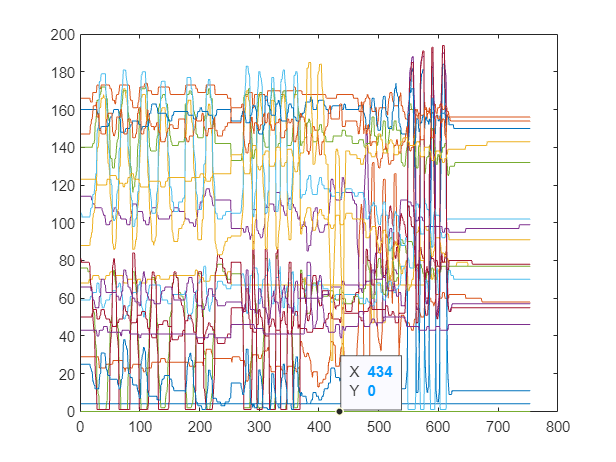

for i = 1:length(nocal(:,1))
    plot(nocal(i,:));
    hold on;
end
hold off

for i = 1:length(cal(:,1))
    plot(cal(i,:));
    hold on;
end

ans =      0   300


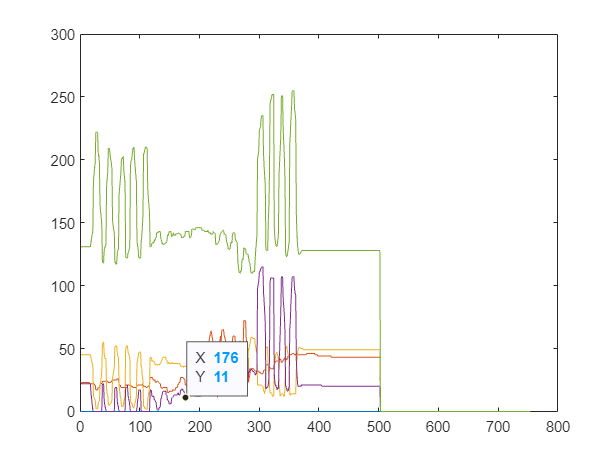

hold off

## Salva Posizione per calibrazione

Da aggiungere la calibrazione del pollice? Polso?

posit = "ext";
tabel = array2table(tab);
tabel.Properties.VariableNames(1:20) = DataTags

save(strcat("\",percorso,"\","cal_",posit,"_",oggi,".mat"),"tab")       % rivedere se funziona
 

## Debug CyberGlove

Per ora serve per valutare velocemente se tutti i sensori funzionano, e osservare non linearità nell tracciato

 
N_DOF = 5;
dof_name = {'Index finger';'Middle finger';'Ring and pinky fingers';'Thumb Flexion';'Thumb abduction'};
channels{1} = [5, 6];
channels{2} = [7, 8];
channels{3} = [10, 11, 13, 14];
channels{4} = [2];
channels{5} = [4];
channels = channels';
T = table(dof_name, channels);
clear dof_name channels
debug_channels = true;
if debug_channels
  StartAcquisition(glove)
  last_pack = 0;
  if glove.pack > 0
    data = (glove.raw_acq)';
  end
  figure
  count = 1;
  while(count < 1000)
    if glove.pack > last_pack
      last_pack = glove.pack;
      data(2:end+1,:) = data(1:end,:);
      data(1,1:19) = (glove.raw_acq)';
      if size(data,1) > 100
        data(end,:) = [];
      end
      for ii = 1:N_DOF
        subplot(2,3,ii)
        plot(data(:,T.channels{ii}))
        legend
        ylim([0 255])
        title(T.dof_name{ii})
      end
      count = count +1;
    end
    pause(0.001)
  end
  StopAcquisition(glove);
end

## Init. Drivers

disp('Settare i MYKI Drivers duh')

Creata cartella datata per oggi: 26-01-23


DRIfreq = input('Inserire valore frequenza scelta:');
DRItorq = input('Inserire valore coppia scelta:');
% salva i due

## Simulazioni MTV-KI con Tactors su tendini estensori

Con questa sezione somministriamo vibrazioni mirate all'onset della suggestione di movimento. L'intento è di arrivare alla sensazione di illusione cinestetica, non di raccogliere dati

quindi l'attenzione ai bias da stimolazioni non random è importante.

vib_index = zeros(3,1);
vib_index(1) = true; vib_index(2) = false; vib_index(3) = false;
disp("Inserire frequenza in Hz")
freq = 10*150;
disp("Inserire gain")
gain = 203;
disp("Inserire durata impulso")
pulse_delta = 1900/2;               % in ms
delay = pulse_delta/10 - 1;                               % in cs (un'unità vale 10 ms)
 

devIndex = 0;                                             % hardcoded

if (ti.deviceConnected == true && vib_index(1) == 1)
    ti.ChangeFreq(devIndex, 1, freq, 0);
    ti.ChangeGain(devIndex, 1, gain, 0);
    ti.Pulse(devIndex,1, pulse_delta, 0);
    ti.Pulse(devIndex, 1, pulse_delta, delay-2);
end
if (ti.deviceConnected == true && vib_index(2) == 1)
    ti.ChangeFreq(devIndex, 2, freq, 0);
    ti.ChangeGain(devIndex, 2, gain, 0);
    ti.Pulse(devIndex, 2, pulse_delta, 1);
    ti.Pulse(devIndex, 2, pulse_delta, delay-1);
end
if (ti.deviceConnected == true && vib_index(3) == 1)
    ti.ChangeFreq(devIndex, 3, freq, 0);
    ti.ChangeGain(devIndex, 3, gain, 0);
    ti.Pulse(devIndex, 3, pulse_delta, 2);
    ti.Pulse(devIndex, 3, pulse_delta, delay);
end

## Test preliminare MYKI questionario eventi illusione cinestetica

Successivamente all'avvenuto onset dell'illusione propriocettiva, e la distinzione di vibrazioni che la suscitano da quelle che non lo fanno, si passa a questa sezione.

Ad ogni vibrazione (dai valori random) si raccolgono risposte ad un questionario.

TODO:

1) Da definire la generazione degli impulsi e il range di valori

2) Definire lunghezza dell'esperimento, può essere utile per

    raccogliere dati su eventuale correlazione tra familiarizzazione con l'illusione cinestetica tendinea esterna e quella magnetica interna

    ma può essere "di troppo" se troppo lungo

3) Definire questionario. Si può domandare su "intensità", "range of motion", "velocità", altro?

% Vibrazione MYKI

% Questionario
    % Hai sentito robe?
    % Su che diciti?

% Registrazione risposte su File Questionario

## Test MYKI con DataGlove

Questa 

% MYKI Driving

% Record DataGlove

% Questionario da decidere

## Funzioni

function [com] = portaseriale(name)
    serials = serialportlist;
    disp('Available serial COMs are: ')
    for i= 1:size(serials,2)
      pause(0.2)
      display(serials{i})
    end
    disp(' ')
    pause(0.5)
    display(strcat('Which one do yo want to open for ', name, '?'))
    pause(0.2)
    prompt = 'COM';
    name = input(prompt);
    com = strcat('COM',num2str(name));
end